# **InverseJacobiND**

[Inverse of the Jacobi elliptic function nd](https://dlmf.nist.gov/22.15)

## Definition


$${\textrm{nd}}^{-1} \left(x\left|m\right.\right)\equiv \left\lbrace \begin{array}{cc}
\mathit{\mathbf{F}}\left(\sqrt{\frac{x^2 -1}{m\;x^2 }}\left|m\right.\right) & -\infty <m\le 1\\
\frac{{\textrm{nc}}^{-1} \left(x\left|m^{-1} \right.\right)}{\sqrt{m}} & 1<m<\infty 
\end{array}\right.$$



$${\mathrm{nd}}^{-1} \left(x,k\right)\equiv {\mathrm{nd}}^{-1} \left(x\left|k^2 \right.\right)$$


where *m *is the parmeter, *k *is the modulus, $\mathit{\mathbf{F}}\left(x\left|m\right.\right)$ is the Jacobi form of the elliptic integral of the first kind.

Domain:   If $-\infty <m<0$ then $0\le x<1/\sqrt{1-m}$ .  If $0\le m\le 1$ then $1\le x<1/\sqrt{1-m}$ . If $m>1$ then $|x|>1$.For the specified domain, the  codomain  is the set of real numbers.

Basic features:

Special values ($m\le 1$):

   ${\textrm{nd}}^{-1} \left(1/\sqrt{1-m}\left|m\right.\right)=K\left(m\right)$,   ${\textrm{nd}}^{-1} \left(1\left|m\right.\right)=0$

${\textrm{nd}}^{-1} \left(x\left|0\right.\right)=\mathrm{NaN}$,    ${\mathrm{nd}}^{-1} \left(x\left|1\right.\right)={\mathrm{cosh}}^{-1} x$

Special values ($m>1$):

   ${\textrm{nd}}^{-1} \left(\pm \infty \left|m\right.\right)=K\left(m\right)$,   ${\textrm{nd}}^{-1} \left(-1\left|m\right.\right)=2K\left(m\right)$,    ${\textrm{nd}}^{-1} \left(1\left|m\right.\right)=0$

Identities:


$${\mathrm{nd}}^{-1} \left(\mathrm{nd}\left(x\left|m\right.\right)\left|m\right.\right)=x,\;\;\;\;\left|x\right|<K\left(m\right)$$



$$\textrm{nd}\left({\textrm{nd}}^{-1} \left(x\left|m\right.\right)\left|m\right.\right)=x\;\;\;\;$$


$K\left(m\right)$ is the complete elliptic integral of the first kind.

## Syntax

Y = InverseJacobiND(X,K)

y = ijnd(x,k)

Y = mInverseJacobiND(X,M)

y = mijnd(x,m)

## Dendription

**Y = InverseJacobiND(X,K)** return${\;\mathrm{nd}}^{-1} \left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the snde size or any of them can be ndalar. **InverseJacobiND** is the wrapper function which calls the functions **ijnd** element-wise via the function **ufun2**.

**y = ijnd(x,k)** return the value of ${\mathrm{nd}}^{-1} \left(x,k\right)$ for argument *x* and the modulus k. It is assumed that the input arguments are real ndalars without check. y is NaN if any of   the input arguments is invalid or convergence failed. **ijnd** is the wrapper function which calls the functions **mijnd**.

**Y = mInverseJacobiND(X,M)** returns ${\mathrm{nd}}^{-1} \left(x\left|m\right.\right)$ for each element of the arrays X and M (parndeter). X and M must be real and the snde size or any of them can be ndalar. **mInverseJacobiND** is the wrapper function which calls the functions **mijnd** element-wise via the function **ufun2**.

**y = mijnd(x,m)** compute value of ${\mathrm{nd}}^{-1} \left(x\left|m\right.\right)$ for  argument x and the parndeter m. It is assumed that the input arguments are real ndalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **mijnd **call the function **melF **for calculation of ${\mathrm{nd}}^{-1} \left(x\left|m\right.\right)$.

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5;
x = 1.1;
[ijnd(x,k), InverseJacobiND(x,k), mijnd(x,k^2), mInverseJacobiND(x,k^2)]

ans =    1.020686381373683   1.020686381373683   1.020686381373683   1.020686381373683


% Maple 1.020686381373682_20


Accuracy.

fprintf('%.16g\n',mijnd(2,4)) 

0.5447753350259427


%  Maple  0.5447753350259427_05

fprintf('%.16g\n',mijnd(0.5,-4)) 

0.7663454616725307


% Maple 0.7663454616725306_65

Special values

m=1.5;
disp(mijnd(1,m))  

     0



m=1.5; % m > 1
disp(mijnd(-1,m)-2*melK(1/m)/sqrt(m))  

     0



m=0.5;
x=1/sqrt(1-m);
disp(mijnd(x,m)-melK(m))

     0



x=1.5;
disp(mijnd(x,0)) 

   NaN



disp(mijnd(x,1) - acosh(x))

     0



Identities

m = 2;
x = 1.5; % x > 1
disp(mJacobiND(mInverseJacobiND(x,m),m)-x)

     4.440892098500626e-16




k = 0.99995;
x = 0.9999*elK(k);
disp(InverseJacobiND(JacobiND(x,k),k)-x)

    -1.819106643097257e-09



m = 2; % m>1
x = 1.2; % 1< x < sqrt(m-1)
disp(mijnd(x,m)-mijnc(x,1/m)/sqrt(m))

     0



**Vector input**

m = [0.1, 0.5, 0.89, 0.99995];
x = 1.02*ones(size(m));
disp(mJacobiND(mInverseJacobiND(x,m),m)-x)

     0     0     0     0



**Matrix input**

m = [0.1, 0.5, 0.89; 1, 97, 0.99995 ];
x = 1.02*ones(size(m));
disp(mJacobiND(mInverseJacobiND(x,m),m)-x)

     0     0     0
     0     0     0



## **Plot **

**Example 1**

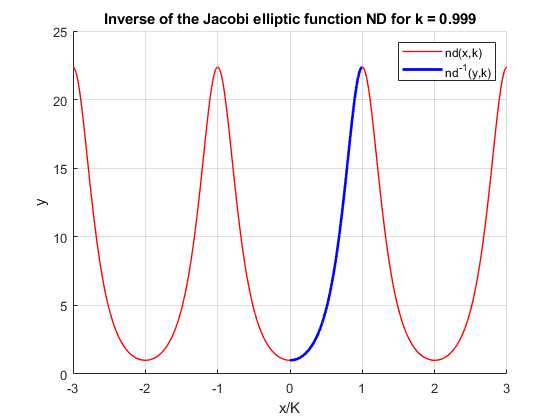

figure
hold on
x=-3:0.01:3;
k = 0.999;
M = elK(k);
plot(x,JacobiND(M*x,k),'LineWidth',1.0,'Color','red')
x=-102:0.01:102;
plot(InverseJacobiND(x,k)/M,x,'LineWidth',2,'Color','blue')
legend('nd(x,k)','nd^{-1}(y,k)') %,'Position','best')
xlabel('x/K')
ylabel('y')
%xlim([-1.1 1.1])
%ylim([-5 5])
title(sprintf('Inverse of the Jacobi elliptic function ND for k = %g',k))
grid on
hold off

**Example 2**

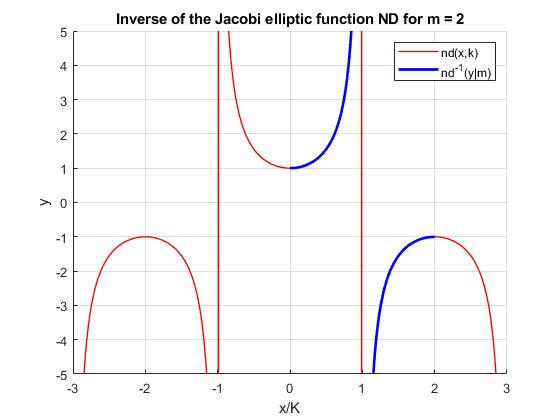

figure
hold on
x=-3:0.01:3;
m = 2;
if m < 1
    M = melK(m);
    xlabel('x/K')
elseif m > 1
    M = melK(1/m)/sqrt(m);
    xlabel('x/K')
    ylim([-5 5])
else
    M = 1;
    xlabel('x')
end
plot(x,mJacobiND(M*x,m),'LineWidth',1.0,'Color','red')
x=-102:0.01:102;
plot(mInverseJacobiND(x,m)/M,x,'LineWidth',2,'Color','blue')
legend('nd(x,k)','nd^{-1}(y|m)') %,'Position','best')
ylabel('y')
%xlim([-1.1 1.1])

title(sprintf('Inverse of the Jacobi elliptic function ND for m = %g',m))
grid on
hold off

**Example 3**

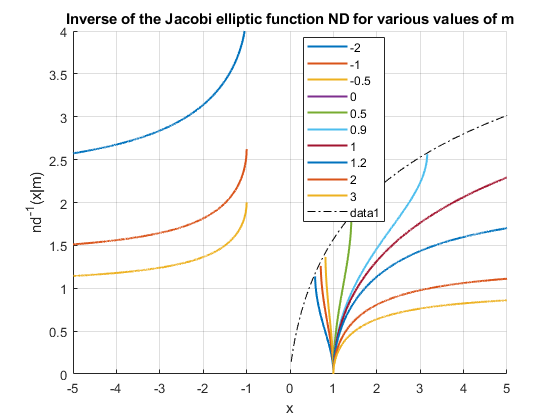

figure
hold on
X = -5:0.001:5;
M = [-2,-1,-0.5,0,0.5,0.9,1,1.2,2,3];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mInverseJacobiND(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) 0 4])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Inverse of the Jacobi elliptic function ND for various values of m')
N=-1200:0.01:1;
X = 1./sqrt(1-N);
plot(X,mEllipticK(N),'k-.'); %mInverseJacobiND(X,N),'k-.')
%plot(-X,mInverseJacobiND(X,N),'k-.')
xlabel('x')
ylabel('nd^{-1}(x|m)')

**Example 4**

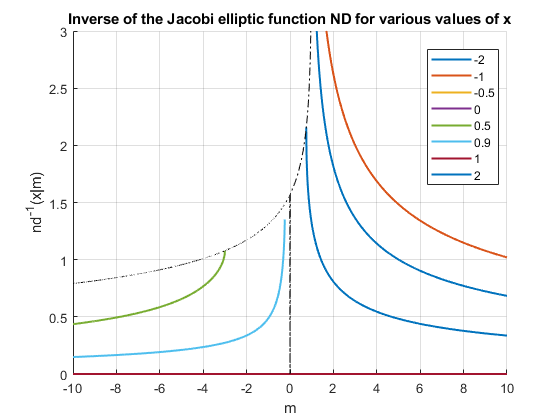

figure
hold on
M = -10:0.01:10;
X = [-2,-1,-0.5,0,0.5,0.9,1,2];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mInverseJacobiND(X(i),M);
end
plot(M,SN,'LineWidth',1.5)
%axis([min(M) max(M) -3 3])
ylim([0  3])
grid on
legend(clg{1:length(X)},'Location','Best')
title('Inverse of the Jacobi elliptic function ND for various values of x')
xlabel('m')
ylabel('nd^{-1}(x|m)')
M = -10:0.01:1;
F = mInverseJacobiND(1./sqrt(1-M),M);
plot(M,F,'k-.')
%plot(M,-F,'k-.')
hold off

**Example 5**

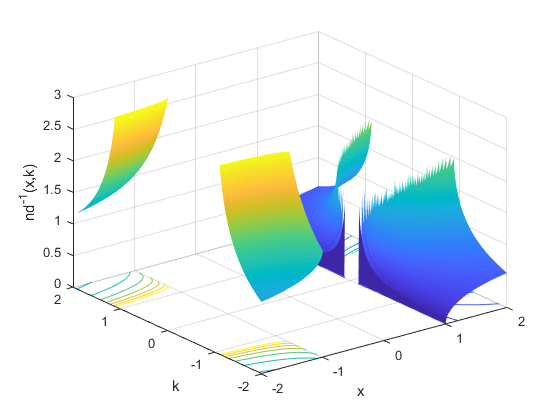

figure
x=-2:0.01:2;
k=-2:0.01:2;
zz = 3;
[X,M]=meshgrid(x,k);
hs=surfc(X,M,InverseJacobiND(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = 0;
hc.LineWidth = 0.5;
hc.LevelList = 0:zz/10:zz;
view(3)
caxis([0 zz])
xlabel('x')
ylabel('k')
zlabel('nd^{-1}(x,k)')
zlim([0 zz])
grid on

**Example 6**

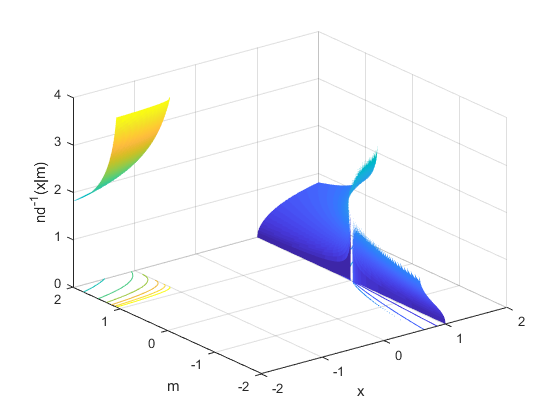

figure
x=-2:0.01:2;
m=-2:0.01:2;
zz = 4;
[X,M]=meshgrid(x,m);
hs=surfc(X,M,mInverseJacobiND(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = 0;
hc.LineWidth = 0.5;
hc.LevelList = 0:zz/10:zz;
view(3)
caxis([0 zz])
xlabel('x')
ylabel('m')
zlabel('nd^{-1}(x|m)')
zlim([0 zz])
grid on

**Example 7**

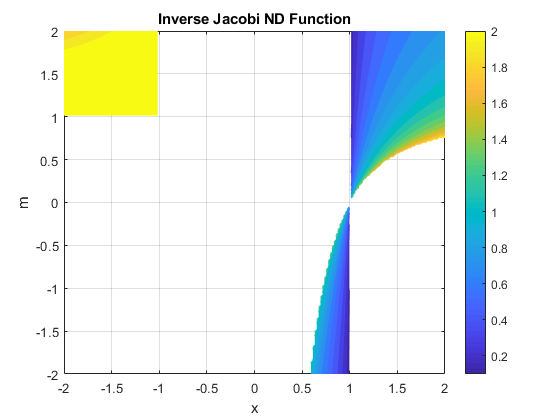

figure
f = @(x,m)mInverseJacobiND(x,m);
fcontour(f,[-2 2 -2 2],'Fill','on','LevelList',-2:0.1:2,'MeshDensity',200)
title('Inverse Jacobi ND Function')
colorbar
xlabel('x')
ylabel('m')
grid on

**Example 8**

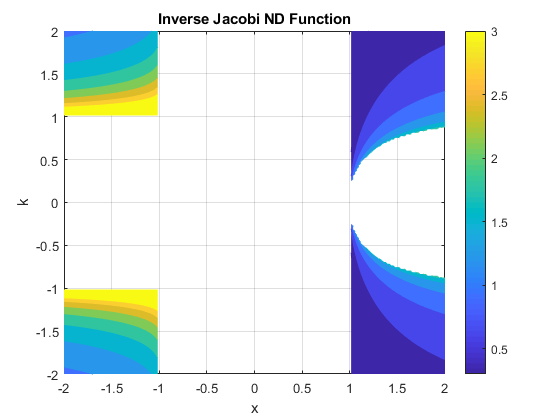

figure
f = @(x,k)InverseJacobiND(x,k);
fcontour(f,[-2 2 -2 2],'Fill','on','LevelList',-3:0.3:3,'MeshDensity',200)
title('Inverse Jacobi ND Function')
colorbar
xlabel('x')
ylabel('k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

## See Also